aspect_ration = 16.0 / 9.0

aspect_ration = 1.7778

image_width = 400

image_width = 400

image_height = image_width / aspect_ration

image_height = 225


viewport_height = 2.0

viewport_height = 2

viewport_width = aspect_ration * viewport_height

viewport_width = 3.5556

focal_length = 1.0

focal_length = 1


origin = [0; 0; 0]

origin =      0
     0
     0


horizontal = [viewport_width; 0; 0]

horizontal =     3.5556
         0
         0


vertical = [0; viewport_height; 0]

vertical =      0
     2
     0



lower_left_corner = origin - horizontal / 2 - vertical / 2 - [0; 0; focal_length]

lower_left_corner =    -1.7778
   -1.0000
   -1.0000


j = image_height - 1

j = 224

i = 043

i = 43

u = i / (image_width-1)

u = 0.1078

v = j / (image_height-1)

v = 1

dir1 = lower_left_corner + vertical

dir1 =    -1.7778
    1.0000
   -1.0000


dir2 = lower_left_corner + horizontal + vertical

dir2 =     1.7778
    1.0000
   -1.0000


dir3 = lower_left_corner + horizontal

dir3 =     1.7778
   -1.0000
   -1.0000


dir4 = lower_left_corner

dir4 =    -1.7778
   -1.0000
   -1.0000


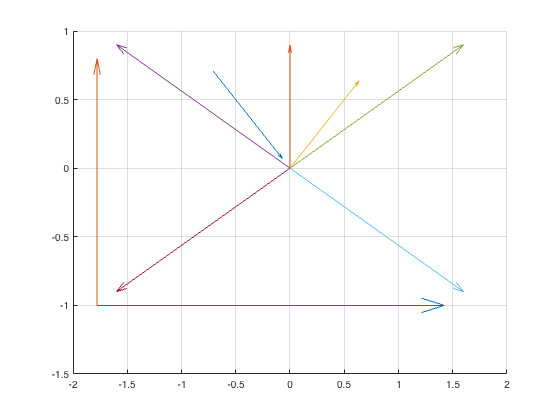

quiver3(origin(1), origin(2), origin(3), dir1(1), dir1(2), dir1(3))
quiver3(origin(1), origin(2), origin(3), dir2(1), dir2(2), dir2(3))
quiver3(origin(1), origin(2), origin(3), dir3(1), dir3(2), dir3(3))
quiver3(origin(1), origin(2), origin(3), dir4(1), dir4(2), dir4(3))
hold on
quiver3(lower_left_corner(1), lower_left_corner(2), lower_left_corner(3), horizontal(1), horizontal(2), horizontal(3))
quiver3(lower_left_corner(1), lower_left_corner(2), lower_left_corner(3), vertical(1), vertical(2), vertical(3))

v = [1; -1; 0]

v =      1
    -1
     0


in = v / norm(v)

in =     0.7071
   -0.7071
         0


n = [0; 1; 0]

n =      0
     1
     0


dot(in, n)

ans = -0.7071

out = in - 2 *  dot(in, n) * n

out =     0.7071
    0.7071
         0


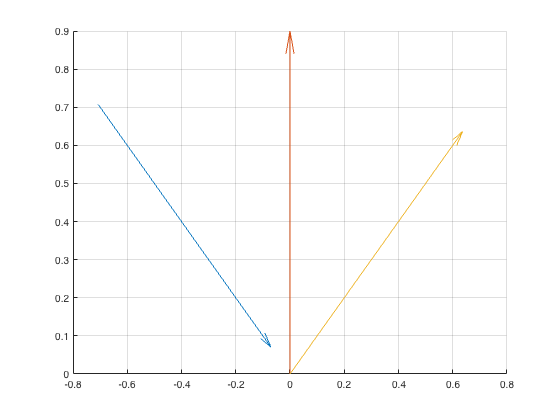

ans = 0

figure;
quiver3(-0.7071, 0.7071, 0.0, in(1), in(2), in(3))
hold on;
quiver3(0, 0, 0, n(1), n(2), n(3))
quiver3(0, 0, 0, out(1), out(2), out(3))
view([0.0 90.00])